%clearvars;close all;clc;

gamma = deg2rad(0);
h = 8 *10^-3;
lambda = 550 * 10^-9;

lens = ThinLens(15, 50, 100);
grid = RefractionGrid(15, 300, 20, 50);

figure(1)
axis equal
set(gca, 'XAxisLocation', 'origin')

grid.Plot;
lens.Plot;

hold on

plot([0 grid.DistanceFromOrigin], [h h], 'red', 'LineWidth', 1)
beta = grid.RayAngle(-1, lambda)

beta = -0.1678

h1 = h - (lens.DistanceFromOrigin - grid.DistanceFromOrigin)*tan(-beta)

h1 = -4.7181e-04

plot([grid.DistanceFromOrigin lens.DistanceFromOrigin], [h h1], 'red')
delta = lens.RayAngle(beta,h1)

delta = 0.1364

h2 = h1 - (lens.DistanceFromOrigin + lens.FocalLength - lens.DistanceFromOrigin)*tan(delta)

h2 = -0.0025

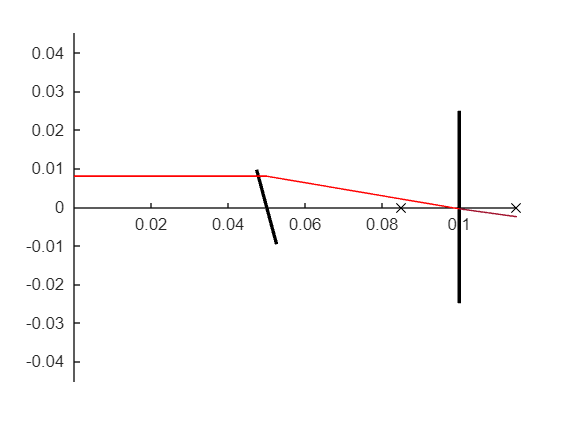

plot([lens.DistanceFromOrigin lens.DistanceFromOrigin+lens.FocalLength], [h1 h2])